# A5 Explicit MPC and Mimimum Time Control

## 1.Linear MPC design

consider the following system

The input and state constraints are

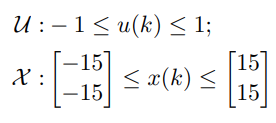

clc
clear
A = [1.2 1; 0 1];
B = [0;1];

model = LTISystem('A', A, 'B', B);     % unstable A
model.x.min = [-15; -15];
model.x.max = [ 15;  15];
model.u.min = -1;
model.u.max =  1;

X = Polyhedron('lb', model.x.min, 'ub', model.x.max);
U = Polyhedron('lb', model.u.min, 'ub', model.u.max);

(a) Consider $Q=I_2,R=100,N=4,X_f=\mathbf{0}$

find a terminal $P_f$for the constrained RHC to guarantee asymptotic stability for all $x_0 \in X_N$

Q = eye(2);
R = 100;
Nsim = 4;
Xf = Polyhedron([0 0]);
C_inf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


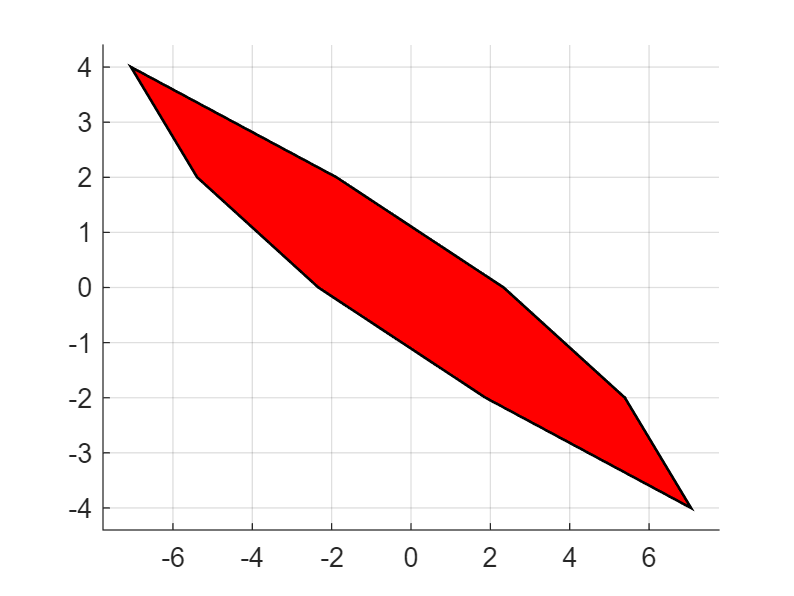


model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);
% terminal weight?
P      = model.LQRPenalty; % i.e. P is the DARE solution for this LQR
model.x.with('terminalPenalty');
model.x.terminalPenalty = P;


% terminal set 
Tset   = Xf;
model.x.with('terminalSet');
model.x.terminalSet = Tset;

% feasible set
XN = Tset;
for i=1:Nsim
    back_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
    XN = back_XN.intersect(X).minHRep();
end
figure
plot(XN)

(b) Set x(0)=[7,-4]T, design a MPC for N = 10, 15, 20.

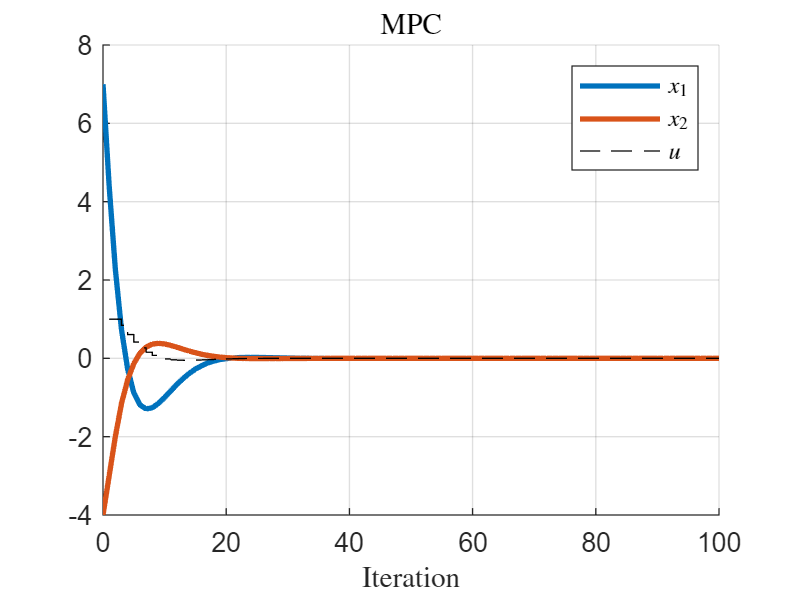

x0 = [7;-4];
Nsim = 100;
% N = 10;
N = 10;
mpc  = MPCController(model, Nsim);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;grid on
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')

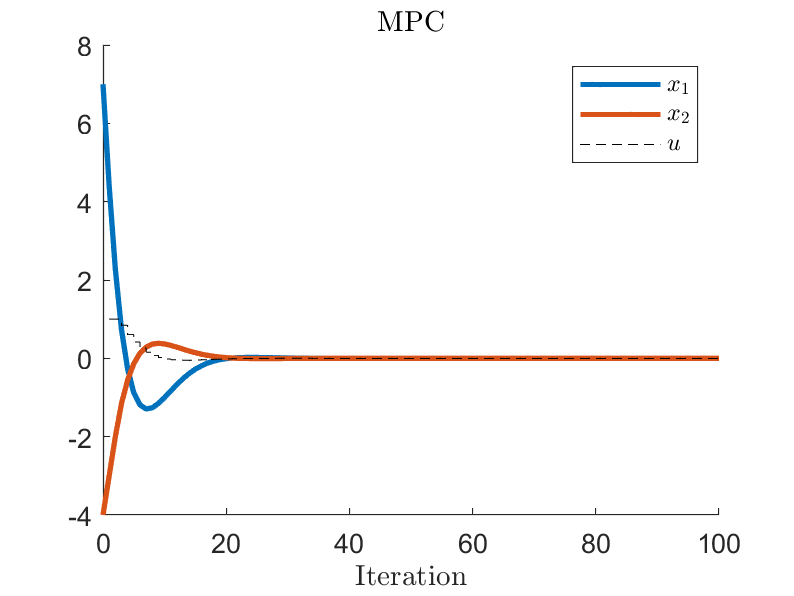


% N = 15;
N = 15;
mpc  = MPCController(model, Nsim);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')


% N = 20;
N = 20;
mpc  = MPCController(model, Nsim);
loop = ClosedLoop(mpc, model);

% Simulate (compare time difference)
data  = loop.simulate(x0, Nsim);
figure 
clf; 
hold on;
plot(0:Nsim,data.X(1,:), 'Linewidth', 2)
plot(0:Nsim,data.X(2,:), 'Linewidth', 2)
stairs(data.U, 'k--')
xlabel('Iteration')
title('MPC')
legend({'$x_1$','$x_2$','$u$'}, 'interpreter', 'latex')